# Problmea 6 - Suplimentar

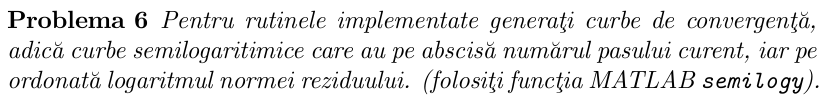

function [x, reziduuri] = jacobi_convergenta(A, b, tol, max_iter)
    n = length(b);
    x = zeros(n,1);
    x_prev = x;
    reziduuri = [];

    D = diag(diag(A));
    R = A - D;

    for k = 1:max_iter
        x = D \ (b - R * x_prev);
        rez = norm(b - A*x);
        reziduuri(end+1) = rez;

        if rez < tol
            break;
        end
        x_prev = x;
    end
end

function [x, reziduuri] = sor_convergenta(A, b, omega, tol, max_iter)
    n = length(b);
    x = zeros(n,1);
    reziduuri = [];

    for k = 1:max_iter
        x_old = x;
        for i = 1:n
            s = A(i,:) * x - A(i,i) * x(i);
            x(i) = (1 - omega) * x_old(i) + omega * (b(i) - s) / A(i,i);
        end
        rez = norm(b - A*x);
        reziduuri(end+1) = rez;

        if rez < tol
            break;
        end
    end
end

A =      5    -1     0     0     0     0     0     0     0     0
    -1     5    -1     0     0     0     0     0     0     0
     0    -1     5    -1     0     0     0     0     0     0
     0     0    -1     5    -1     0     0     0     0     0
     0     0     0    -1     5    -1     0     0     0     0
     0     0     0     0    -1     5    -1     0     0     0
     0     0     0     0     0    -1     5    -1     0     0
     0     0     0     0     0     0    -1     5    -1     0
     0     0     0     0     0     0     0    -1     5    -1
     0     0     0     0     0     0     0     0    -1     5


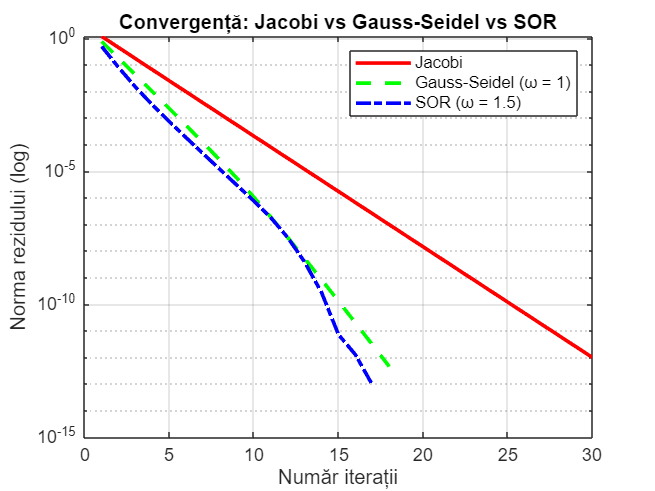

function problema6_convergenta()
    % Definim un sistem simplu pentru testare
    n = 10;
    A = 5 * eye(n) - diag(ones(n-1,1), 1) - diag(ones(n-1,1), -1) % tridiagonală
    b = ones(n, 1);  % soluția exactă
    tol = 1e-12;
    max_iter = 500;

    % Parametru relaxare SOR
    omega_opt = 1.1;
    omega_gs  = 1;   % Gauss-Seidel = SOR cu w=1

    % Colectăm reziduuri
    [~, res_jacobi] = jacobi_convergenta(A, b, tol, max_iter);
    [~, res_sor_opt] = sor_convergenta(A, b, omega_opt, tol, max_iter);
    [~, res_sor_gs]  = sor_convergenta(A, b, omega_gs,  tol, max_iter);

    % Plotare rezultate
    figure;
    semilogy(res_jacobi, 'r-', 'LineWidth', 2); hold on;
    semilogy(res_sor_gs,  'g--', 'LineWidth', 2);
    semilogy(res_sor_opt, 'b-.', 'LineWidth', 2);

    xlabel('Număr iterații');
    ylabel('Norma rezidului (log)');
    title('Convergență: Jacobi vs Gauss-Seidel vs SOR');
    legend('Jacobi', 'Gauss-Seidel (ω = 1)', 'SOR (ω = 1.5)', 'Location', 'northeast');
    grid on;
end

problema6_convergenta